data=readtable("elevator_test2.csv")

data = 142×15 table
    TimeSinceLaunch_ms_    XAcceleration_m_s_    YAcceleration_m_s_    ZAcceleration_m_s_    XOrientation    YOrientation    ZOrientation    GlobalZAccel    Altitude_m_    Latitude    Longitude    Phase    KalmanAltitude    GlobalZVel    KalmanGlobalZAccel
    ___________________    __________________    __________________    __________________    ____________    ____________    ____________    ____________    ___________    ________    _________    _____    ______________    __________

% break_points = [];
% for i=2:length(data.TimeSinceLaunch_ms_)
%     if data.TimeSinceLaunch_ms_(i) < data.TimeSinceLaunch_ms_(i-1)
%         break_points(end+1) = i;
%     end
% end

break_points

break_points = 56

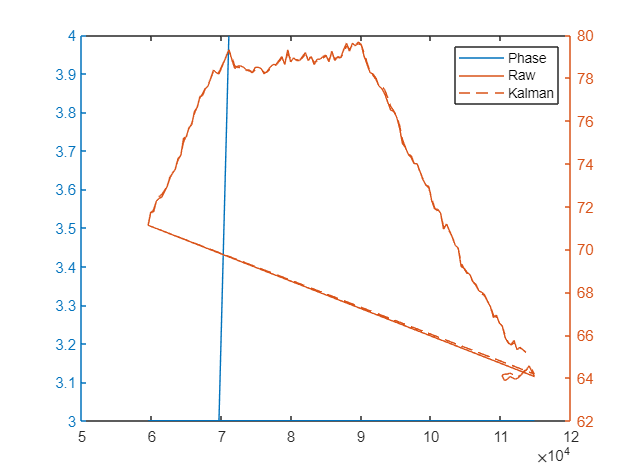

clf


yyaxis left
plot(data.TimeSinceLaunch_ms_, data.Phase)

yyaxis right

plot(data.TimeSinceLaunch_ms_, data.Altitude_m_)
hold on
plot(data.TimeSinceLaunch_ms_, data.KalmanAltitude)
legend("Phase", "Raw", "Kalman")

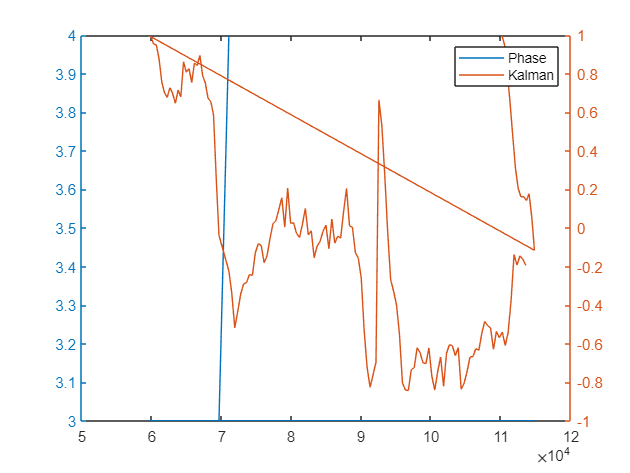

clf


yyaxis left
plot(data.TimeSinceLaunch_ms_, data.Phase)

yyaxis right


plot(data.TimeSinceLaunch_ms_, data.GlobalZVel)
legend("Phase", "Kalman")